close all
clear
clc


## the construction the equation


k1=1;
k2=5;
k3=3;
x1s=0.6; % x1 star 0.6
x3s=x1s^0.5; % x3 star 
x2s=0;
b=0.2;
c=2.6;
b2=b;
b3=2*x3s;
c1=c*x3s;
c3=c*(x1s-1);
c13=c;
tf=10;
x0=[0;0;0];
y0=[0-x1s;0-x2s;0-x3s]

y0 =    -0.6000
         0
   -0.7746


% y0=[0.1;0.1;0]
f1=@(y2) y2;
f2=@(y1,y2,y3) -y1-b2*y2+b3*y3+y3.^2;
f3=@(y1,y3,v) c1*y1+c3*y3+c13*y1.*y3+mysaturation(v, -3,3);
f=@(y1,y2,y3,v) [f1(y2);f2(y1,y2,y3);f3(y1,y3,v)]

f = 包含以下值的 function_handle :
    @(y1,y2,y3,v)[f1(y2);f2(y1,y2,y3);f3(y1,y3,v)]


z2=@(y1,y2) k1*y1+y2; % 改动
k=@(y3) b3*y3+y3.^2;
phi=@(y1,y2,z2) (k1-k2)*z2+b2*y2-k1^2*y1; % 改动
z3=@(k,phi) k-phi;
Dy1=@(y2) y2; %改动
Dy2=@(y1,y2,y3) -y1-b2*y2+b3*y3+y3.^2;
Dy3=@(y3,z3,Dy1,Dy2) ((-k1-k2+b2)*Dy2-k3*z3-k1*k2*Dy1)./(b3+2*y3)% 改动 again +dv/y2

Dy3 = 包含以下值的 function_handle :
    @(y3,z3,Dy1,Dy2)((-k1-k2+b2)*Dy2-k3*z3-k1*k2*Dy1)./(b3+2*y3)


v=@(y1,y3,Dy3) Dy3-c1*y1-c3*y3-c13*y1.*y3;
sol=ode45(@(t,y)f(y(1),y(2),y(3),v(y(1),y(3),Dy3(y(3),z3(k(y(3)),phi(y(1),y(2),z2(y(1),y(2)))),Dy1(y(2)),Dy2(y(1),y(2),y(3))))), [0,tf], y0)

sol = 包含以下字段的 struct :
     solver: 'ode45'
    extdata: [1×1 struct]
          x: [0 0.0445 0.1353 0.2771 0.5000 0.6332 0.7665 0.8981 1.0527 1.2285 1.4162 1.6260 1.8851 2.1441 2.4036 2.6406 2.8790 3.1216 3.3676 3.6118 3.8428 4.1758 4.6477 5.1309 5.5402 5.9490 6.3078 6.6632 7.0993 7.6483 8.2463 8.8867 9.2646 9.6426 10]
          y: [3×35 double]
      stats: [1×1 struct]
      idata: [1×1 struct]


t=linspace(0,tf,200)

t =          0    0.0503    0.1005    0.1508    0.2010    0.2513    0.3015    0.3518    0.4020    0.4523    0.5025    0.5528    0.6030    0.6533    0.7035    0.7538    0.8040    0.8543    0.9045    0.9548    1.0050    1.0553    1.1055    1.1558    1.2060    1.2563    1.3065    1.3568    1.4070    1.4573    1.5075    1.5578    1.6080    1.6583    1.7085    1.7588    1.8090    1.8593    1.9095    1.9598    2.0101    2.0603    2.1106    2.1608    2.2111    2.2613    2.3116    2.3618    2.4121    2.4623


y=deval(sol,t)

y =    -0.6000   -0.6000   -0.5999   -0.5995   -0.5986   -0.5968   -0.5937   -0.5889   -0.5821   -0.5734   -0.5625   -0.5497   -0.5351   -0.5189   -0.5013   -0.4825   -0.4628   -0.4423   -0.4212   -0.3998   -0.3781   -0.3564   -0.3348   -0.3134   -0.2923   -0.2717   -0.2515   -0.2319   -0.2130   -0.1947   -0.1772   -0.1604   -0.1445   -0.1293   -0.1150   -0.1014   -0.0887   -0.0768   -0.0657   -0.0554   -0.0459   -0.0370   -0.0289   -0.0215   -0.0148   -0.0087   -0.0032    0.0017    0.0061    0.0100
         0    0.0005    0.0037    0.0116    0.0258    0.0475    0.0774    0.1142    0.1547    0.1959    0.2360    0.2734    0.3072    0.3370    0.3626    0.3839    0.4010    0.4141    0.4234    0.4292    0.4318    0.4315    0.4285    0.4232    0.4158    0.4065    0.3957    0.3835    0.3703    0.3561    0.3411    0.3256    0.3097    0.2936    0.2773    0.2610    0.2448    0.2288    0.2131    0.1977    0.1827    0.1682    0.1542    0.1407    0.1277    0.1154    0.1036    0.0925    0.0820    0

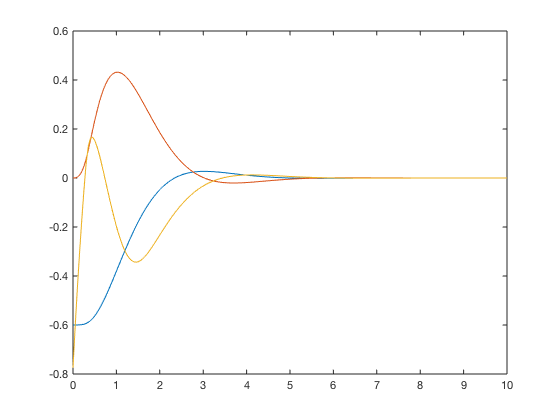


figure(1)
plot(t,y(1,:));
hold on
plot(t,y(2,:));
hold on
plot(t,y(3,:));

% figure(3)
% plot(t,Dy3)

% figure(2)
% v1(:)=mysaturation(v(y(1,:),y(3,:),Dy3(y(3,:),z3(k(y(3,:)),phi(y(1,:),y(2,:),z2(y(1,:),y(2,:)))),Dy1(y(2,:)),Dy2(y(1,:),y(2,:),y(3,:)))), -1,1)
% plot(t,v1(:))
%legend('x1','x2','x3');

%matlab Function

function out = mysaturation(v, low, up)
if v > up
    out = up;
elseif v < low
    out = low;
else
    out = v;
end
end


